% Read in original RGB image.
rgbImage = imread('Tongue Pic. - Gulshan Rai.jpg');
grayImage=rgb2gray(rgbImage)

grayImage = 2488×2039 uint8 matrix
   155   155   154   154   154   154   154   154   155   155   154   153   153   153   154   154   153   153   154   154   154   154   154   153   153   153   153   153   153   153   153   153   152   152   152   153   153   153   154   154   155   154   153   152   151   151   152   153   149   149
   155   155   155   155   155   155   155   155   155   155   154   154   154   154   154   154   153   153   153   154   154   154   154   154   153   153   153   153   153   153   153   153   152   152   152   153   153   153   154   154   154   154   153   152   152   152   153   153   149   149
   156   156   156   156   155   155   155   155   155   155   155   155   155   155   154   154   153   153   153   153   153   153   154   154   153   153   153   153   153   153   153   153   153   153   153   153   153   153   154   154   153   153   153   153   153   153   153   153   150   150
   156   156   156   156   155   155   155   155   156   156  

K = medfilt2(grayImage)

K = 2488×2039 uint8 matrix
     0   155   154   154   154   154   154   154   155   154   154   153   153   153   154   153   153   153   153   154   154   154   154   153   153   153   153   153   153   153   153   152   152   152   152   152   153   153   153   154   154   153   152   152   151   151   152   149   149   149
   155   155   155   155   155   155   155   155   155   155   155   154   154   154   154   154   153   153   153   154   154   154   154   154   153   153   153   153   153   153   153   153   153   152   153   153   153   153   154   154   154   153   153   153   152   152   153   153   150   149
   155   156   156   155   155   155   155   155   155   155   155   155   155   154   154   154   153   153   153   153   153   154   154   154   154   153   153   153   153   153   153   153   153   153   153   153   153   153   154   154   154   153   153   153   153   153   153   152   150   150
   156   156   156   155   155   155   155   155   155   156   156   1

Contrast_Enhance=histeq(K);

T1 = graythresh(Contrast_Enhance)

T1 = 0.5059

B = imsharpen(Contrast_Enhance)

B = 2488×2039 uint8 matrix
     0   255   230   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   224   217   217   224   218   219   219
   255   238   225   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   224   224   224   224   218   219
   228   231   229   222   223   223   223   223   223   222   222   222   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   223   224   218   219
   228   228   228   222   223   223   223   223   222   228   228   2

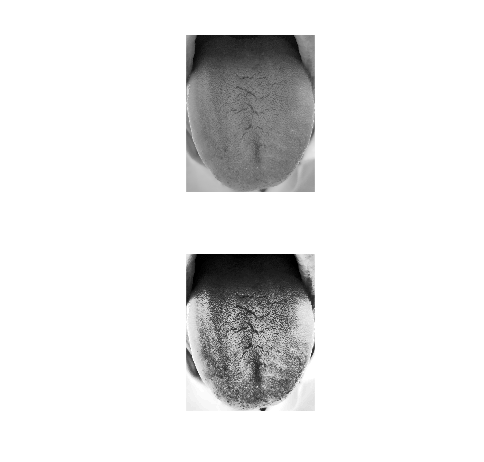

subplot(211)
imshow(grayImage)
subplot(212)
imshow(B)

clc
clear all
close all
Input_Im=imread('PXL_20211227_100311186 - Madhav Chauhan.jpg');
a=rgb2gray(Input_Im)

a = 256×256 uint8 matrix
   100    96   105   104    88    87    95    92    91   102   115   123   127   125   117   108   104   102    99    97    94    89    84    80    74    80    85    82    74    70    72    76    73    72    68    64    65    67    66    62    67    71    76    78    78    79    82    86    92    87
    91    94   101   102    93    92    97    98    98   106   115   118   120   119   113   107   102    99    95    91    88    85    81    79    75    77    78    77    74    73    73    75    75    65    59    62    66    66    68    72    71    74    77    78    77    79    83    87    85    83
    85    95    99    99   100    98    99   106   106   112   115   113   112   112   110   107   101    97    92    87    85    82    80    79    75    74    73    73    74    74    74    74    74    60    55    66    72    68    68    75    76    77    78    78    79    81    85    88    84    83
    90   103   101    99   105   101    98   110   110   114   116   112

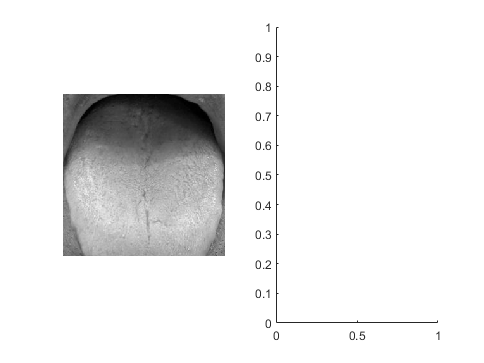

% %=======================================================================
% %=======================================================================
% This function computes the LBP transformation of the input image
% Input_Im. 
% The parameters of the LBP operator are (P = 8, R), 
% where P - the number of sampling points in the region with the radius R. 
% Radius R is the input parameter of the function.
% Possible values for R = 1, 2, 3, etc.
% If input image is COLOR, then the grayscale transformation is performed.
% %=======================================================================
% %=======================================================================
if size(Input_Im, 3) == 3
    Input_Im = rgb2gray(Input_Im);
end;
R=1;
L = 2*R + 1; %% The size of the LBP label
C = round(L/2);
Input_Im = uint8(Input_Im);
row_max = size(Input_Im,1)-L+1;
col_max = size(Input_Im,2)-L+1;
LBP_Im = zeros(row_max, col_max);
for i = 1:row_max
    for j = 1:col_max
        A = Input_Im(i:i+L-1, j:j+L-1);
        A = A-A(C,C);
        A(A>0) = 1;
        LBP_Im(i,j) = A(C,L) + A(L,L)*2 + A(L,C)*4 + A(L,1)*8 + A(C,1)*16 + A(1,1)*32 + A(1,C)*64 + A(1,L)*128;
    end
end
subplot(121)
imshow(a)
subplot(122)

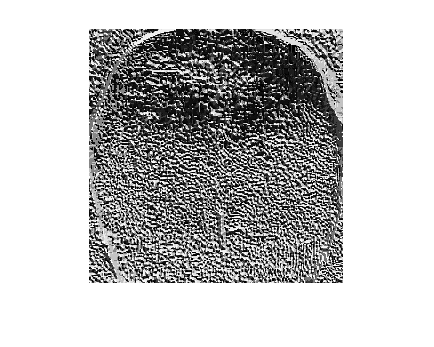

figure,imshow(LBP_Im,[])